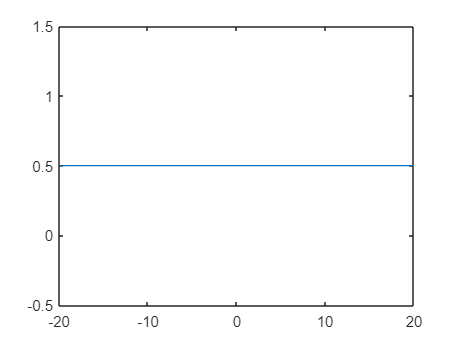

t=0:1:10;
x=myunit(t);
T=2*pi;
w=-20:1:20;
omega = -20:1:20;
phase = zeros(size(omega));
mag = zeros(size(omega));
for w0=1:1:length(w)
    w1=w(w0);
    basis=exp(-1j*w1*t);
    a(w0)=trapz(t,x.*basis);
    phase(w0) = angle(a(w0));
    mag(w0) = abs(a(w0));
end
plot(w,real(a));

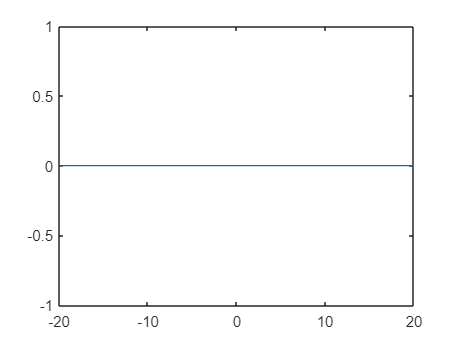

plot(omega,phase);

plot(omega,mag);

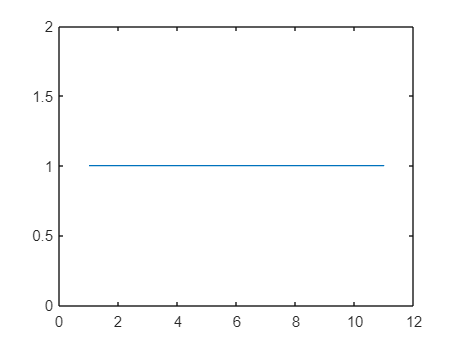

a1=fft(x);

plot(a1)

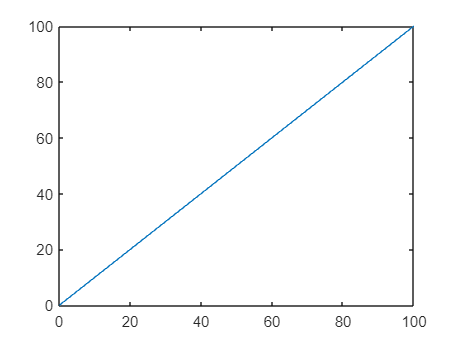

t=0:1:100;
T=5;
x=ramp(t);
plot(t,x);

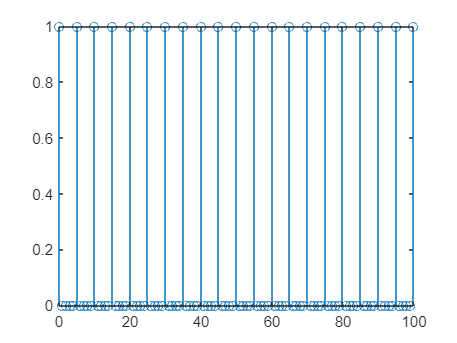

p=P(t,T);
stem(t,p);

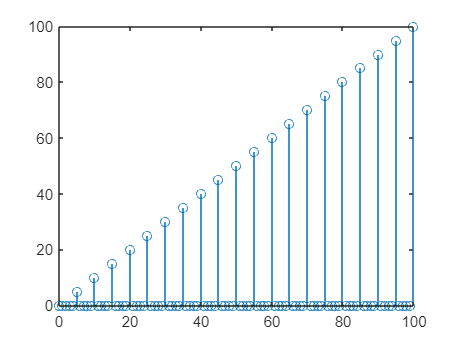

sa=x.*p;
stem(t,sa);

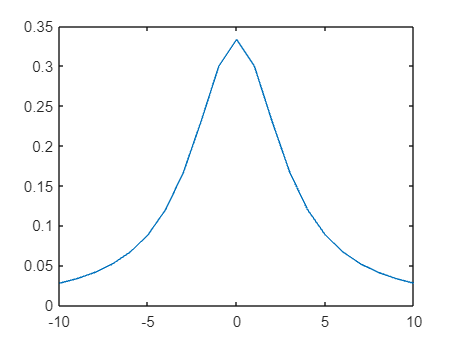

syms t;
a = 3;
x = exp(-a*t);
xw = zeros(size(-10:10));
mag = zeros(size(-10:10));
phase = zeros(size(-10:10));
for w=-10:10
    xw(w+11) = int(x*exp(-1j*w*t),t,0,inf);
    mag(w+11) = abs(xw(w+11));
    phase(w+11) = angle(xw(w+11));
end
w = -10:10;
plot(w,xw);

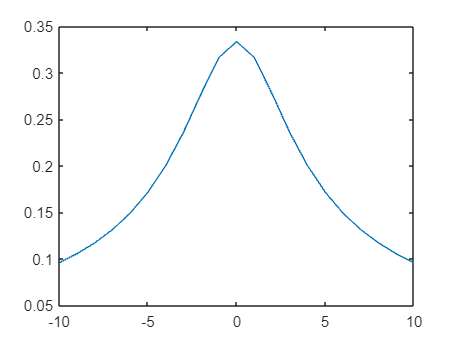

plot(w,mag);

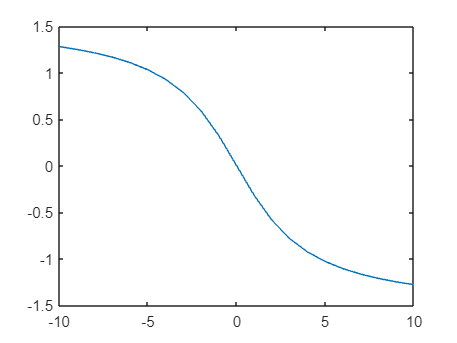

plot(w,phase);

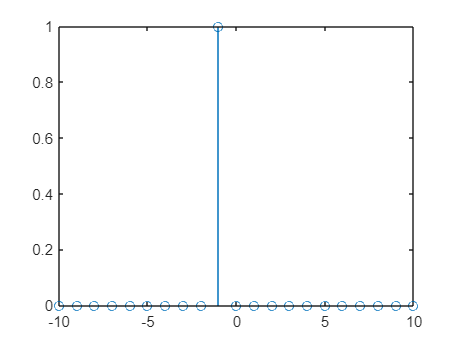

syms w;
x = exp(1j*w);
xt = zeros(size(-10:10));
for t = -10:10
    xt(t+11) = (1/(2.*pi)).*int(x*exp(1j*w*t),w,-pi,pi);
end
t = -10:10;
stem(t,xt);